# Embedded Digital Controllers - System

### Parameters

format('default')
Ts = 0.005;
R = 4.9

R = 4.9000

I = 0.0059

I = 0.0059

L = 8.2*10^(-3)

L = 0.0082

k = 0.8814

k = 0.8814

b = 0.016

b = 0.0160

PWMFreq = 2000

PWMFreq = 2000

### Model

A = [0 1 0; 0 -b/I k/I; 0 -k/L -R/L]

A =          0    1.0000         0
         0   -2.7119  149.3898
         0 -107.4878 -597.5610


B = [0; 0; 1/L]

B =          0
         0
  121.9512


C = [1 0 0]

C =      1     0     0


D = 0

D = 0

[num, den] = ss2tf(A,B,C,D)

num = 1.0e+04 *

         0         0         0    1.8218


den = 1.0e+04 *

    0.0001    0.0600    1.7678         0


G = tf(num*9.5493, den)

G =
 
            1.74e05
  ----------------------------
  s^3 + 600.3 s^2 + 1.768e04 s
 
Continuous-time transfer function.
Model Properties


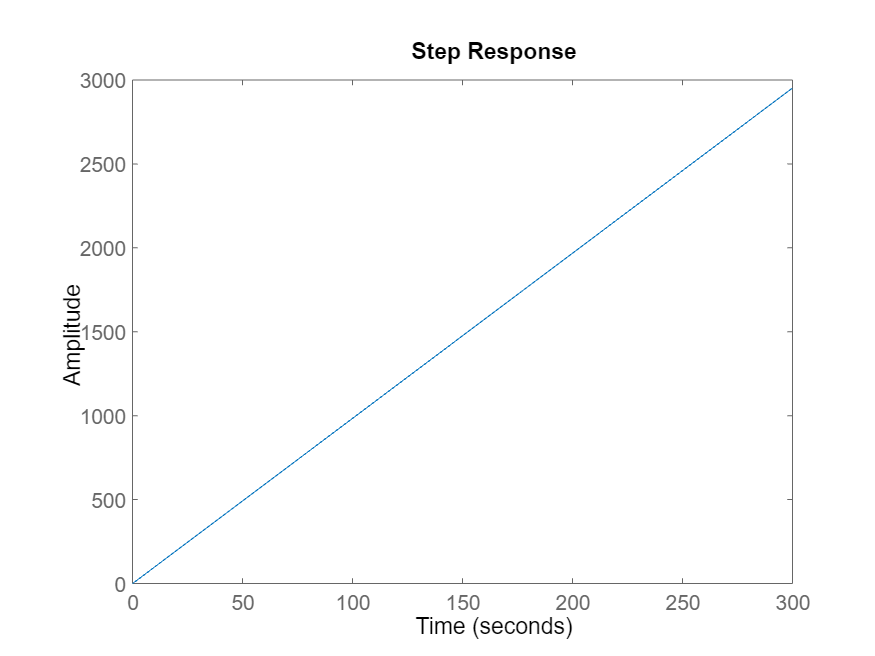

step(G)

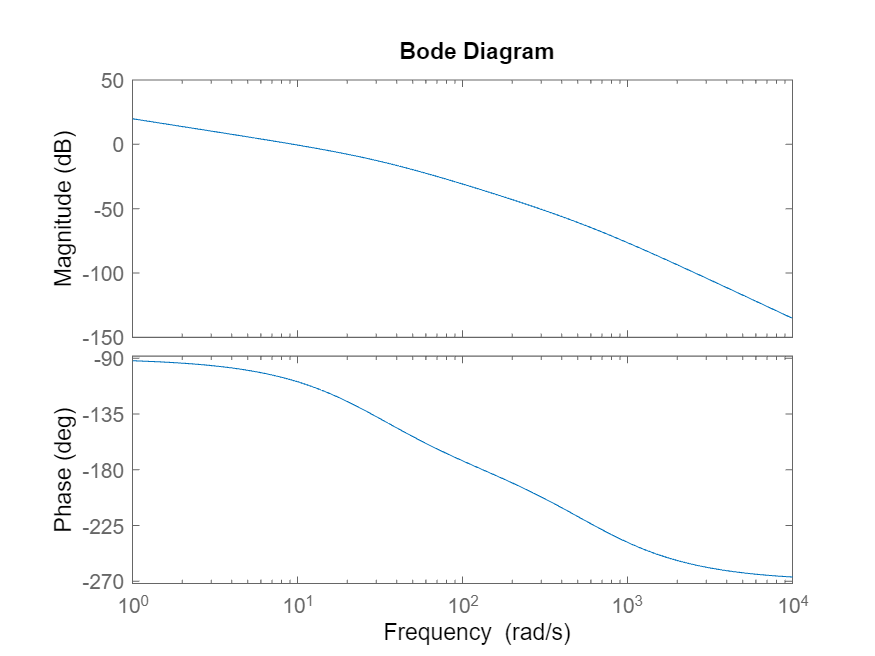

bode(G)

num1 = [0 0 167773.98]

num1 = 1.0e+05 *

         0         0    1.6777


den1 = [1 392.96 15992.15]

den1 = 1.0e+04 *

    0.0001    0.0393    1.5992


G1 = tf(num1, den1)

G1 =
 
         1.678e05
  ----------------------
  s^2 + 393 s + 1.599e04
 
Continuous-time transfer function.
Model Properties


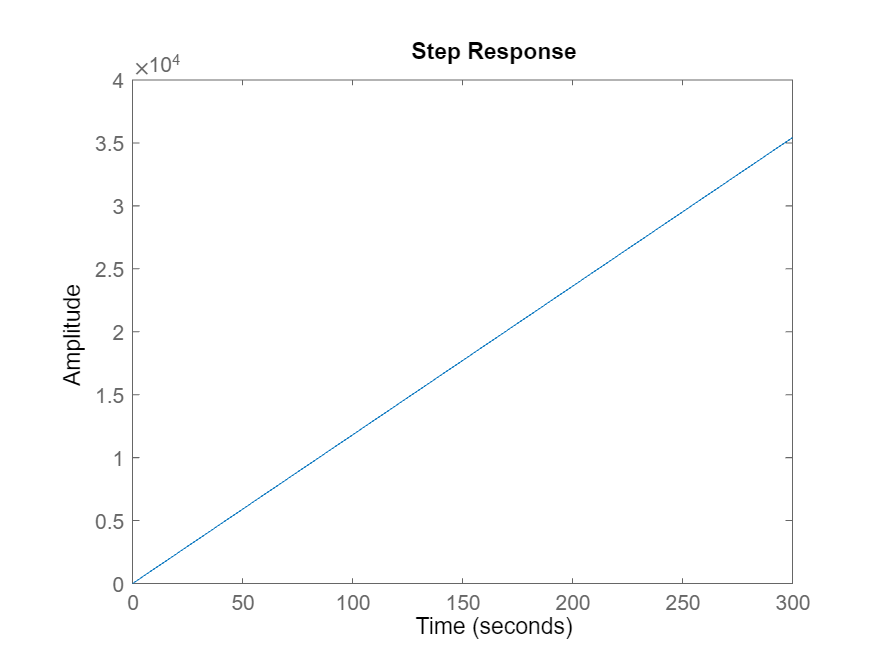

step(G*12)


den = [1 600.3 1.768e04];
poles = roots(den);

real_parts = real(poles);
if all(real_parts < 0)
    disp("Il sistema è stabile.")
else
    disp("Il sistema non è stabile.")
end

Il sistema è stabile.


syms s
eig(A-s*eye(3))

$$ans = \left(\begin{array}{c} -s\\ -s-\frac{\sqrt{423675143038}}{2419}-\frac{726030}{2419}\\ \frac{\sqrt{423675143038}}{2419}-s-\frac{726030}{2419} \end{array}\right)$$

At = [0 1 0 0; 0 -b/I k/I 0 ; 0 -k/L -R/L 0; 1 0 0 0]

At =          0    1.0000         0         0
         0   -2.7119  149.3898         0
         0 -107.4878 -597.5610         0
    1.0000         0         0         0


Bt = [0; 0; 1; 0]

Bt =      0
     0
     1
     0


### Raggiungibility & Observability

W_R = [B A*B A^2*B ];
rankWR = rank(W_R);

W_O = [C;C*A;C*A^2];
rankWO = rank(W_O);

if rankWR == 3
    disp("Sistema Raggiungibile")
end

Sistema Raggiungibile


if rankWO == 3
    disp("Sistema Osservabile")
end

Sistema Osservabile


### Observer

Qxobs = [1000 0 0; 0 1 0; 0 0 1]

Qxobs =         1000           0           0
           0           1           0
           0           0           1


Quobs = [1]

Quobs = 1

L_o = lqr(A.', C.', Qxobs, Quobs);
L_o = L_o.'

L_o =    31.6228
    0.0003
   -0.0001


### LQR

Qx = [10 0 0 0; 0 1 0 0; 0 0 10 0; 0 0 0 1000]

Qx =           10           0           0           0
           0           1           0           0
           0           0          10           0
           0           0           0        1000


Qu = [0.01]

Qu = 0.0100

[Kp,S,P] = lqr(At,Bt,Qx,Qu);

Kp

Kp =   286.4037    9.7206    3.2580  316.2278
